# Propagation d'une onde acoustique dans l'air

### Définition des paramètres principaux

clear;clc;
ro0 = 1.2; % Masse vomumique de l'air
c0 = 350; % Célérité de l'onde dans l'air
chi0 = 1 / (c0^2 * ro0);
T0 = 293; % Temperature ambiante (K) 20°C
P0 = 1e5; %  Pression ambiante (Pa) (10^5 Pa)

L = 2; % Longueur du tube (m)
x_min = 0; % Abscisse du début du trombone (m)
ns = 1000; % Nombre de points spatial

f = 440; % Fréquence de l'onde (Hz)
t_min = 0; % temps initial (s)
t_max = L/c0; %temps final (s)
nt = 20; %nombre de points temporels
t = linspace(t_min, t_max, nt);


### Définition des paramètres secondaires

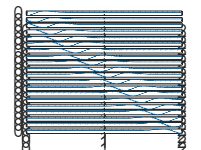


 lambda = c0/f; % Longueur caractéristique de l'onde (m)
T = lambda / c0; % Période temporelle de l'onde
x_max = x_min + L;
Scale = 4/lambda;

xx = x_min:L/ns:x_max;% Vecteur de position x avec un pas de L/ns
z = Scale * xx; % Décalage de la position de l'onde en fonction de Scale et xx
%Onde = ones(ns, nt);
for i=1:nt
    z = Scale * (xx - c0*t(i));% Mise à jour de la variable z en fonction du temps
    [G, DG, DDG] = LesGauss(z);% Calcul des valeurs G, DG et DDG à partir de la fonction LesGauss
    Onde(:, i) = DDG;% Stockage des valeurs de DDG dans la colonne i de la matrice Onde
end
figure(1)
for i=1:nt
    subplot(nt, 1, i);% Création d'un sous-graphique dans une grille de nt lignes et 1 colonne
    plot(xx, Onde(:,i));% Tracé du graphique de l'onde à partir des valeurs stockées dans la colonne i de la matrice Onde
    %pause(0.1);
end

### En dimension 2

y_min = 0;
y_max = y_min  ;
y = y_min:(y_max-y_min)/ns:y_max;
